# Clear workspace

close all
clear all
warning('off','all')

% fix the seed of the random number generator
rng("default");

clc

## Load the data

data_dir = "Data/";

% Load the data from the DEEEX.xlsx file
table_swaps = readtable(data_dir + "DataDEEEX.xlsx", 'Sheet', 'F');
table_options = readtable(data_dir + "DataDEEEX.xlsx", 'Sheet', 'OptionsONQ42024');
table_ois = readtable(data_dir + "DataDEEEX.xlsx", 'Sheet', 'ois');

% add functions to the path
addpath("functions/");

## Dates of discount factors

number_days = 365; % number of days in a year
dates = table_ois(1, 1:end).Variables + 693960; % dates + adjustment to matlab date format

% take differences between the dates and today (04/11/2023)
% we need to convert the dates to datenum format
dates = dates - datenum('04/11/2023', 'dd/mm/yyyy');
dates = dates / number_days; % convert to fraction of (business) year

## Discount factors

OIS_DF = table_ois(2, 1:end).Variables; % discount factors

## Calibration set-up

F0 = table_swaps(end, end).Variables; % swap price at time 0
K = table_options(1, 2:end).Variables; % strike prices
T = table_options(2:end, 1).Variables; % maturities
DF = discountFactor(OIS_DF, dates, T); % discount factors at the maturities of the options
volatilities = table_options(2:end, 2:end).Variables; % real market implied volatilities
max_volatility = max(volatilities, [], "all"); % maximum volatility
% convert the volatilities to sigma hat (volatility * sqrt(T))
market_prices = volsToPrices(F0, K, T, DF, volatilities); % market prices of the options
% expiry of the swap
T1 = datenum(table_swaps(end, 1).Variables);
T1 = T1 - datenum('04/11/2023', 'dd/mm/yyyy');
T1 = T1 / number_days; % convert to fraction of (business) year
% maturity of the swap
T2 = datenum('31/12/2024', 'dd/mm/yyyy');
T2 = T2 - datenum('04/11/2023', 'dd/mm/yyyy');
T2 = T2 / number_days; % convert to fraction of (business) year

## Plot the prices and the volatilities

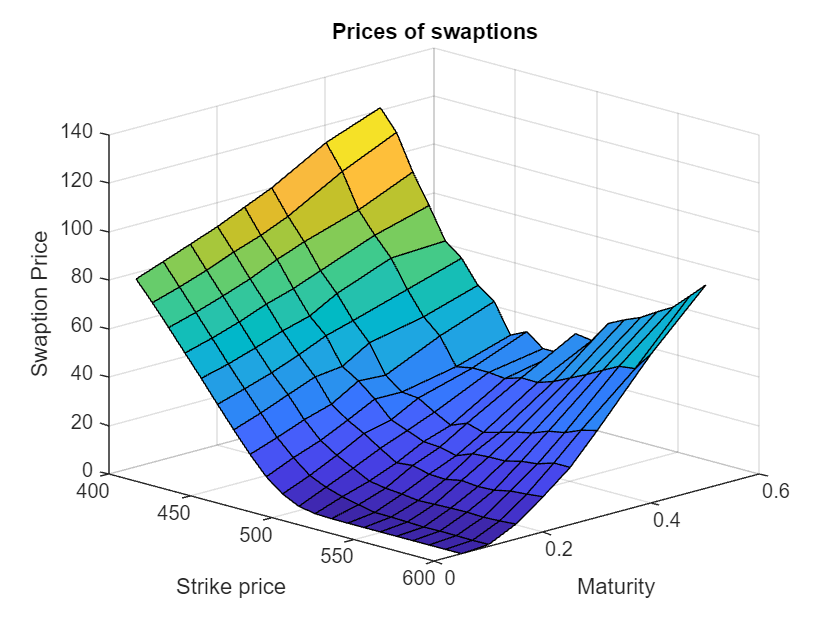

% plot the prices
figure; hold on
grid on
surf(K, T, market_prices);
xlabel('Strike price'); ylabel('Maturity'); zlabel('Swaption Price')
title('Prices of swaptions');
view(45,20)

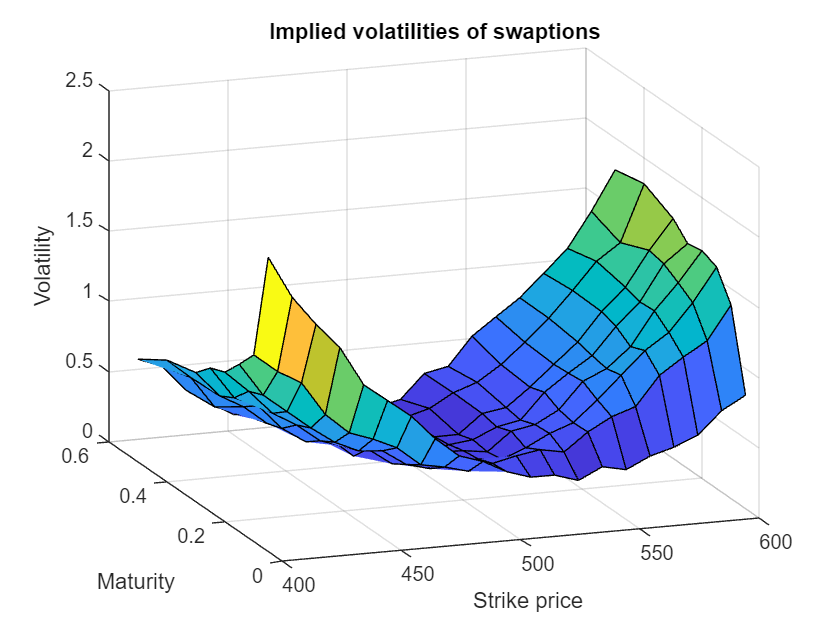


% plot the volatilities
figure; hold on
grid on
surf(K, T, volatilities);
xlabel('Strike price'); ylabel('Maturity'); zlabel('Volatility');
title('Implied volatilities of swaptions');
view(-20,20);

## Point III: Calibrate the model using the Black-76 formula

% Use the MSE as error function
func = @(x) MSE(market_prices, constantVolatilitySwaption(x(1), x(2), F0, K, T, DF));

lb = [0, 0]; % lower bounds (variance must be stricly positive)

% initial guess, two random numbers between 0 and 1
x0 = max_volatility * rand(1, 2);

% use fmincon to minimize the error function
[x_const, fval_const] = fmincon(func, x0, [], [], [], [], lb)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_const =     0.2985    0.2973


fval_const = 185.0994

## Compute the model prices and volatilities

% compute the model prices and volatilities
[model_prices_const, model_volatilities_const] = constantVolatilitySwaption( ...
    x_const(1), x_const(2), F0, K, T, DF);

% print the results
x_const

x_const =     0.2985    0.2973


fval_const

fval_const = 185.0994

## Plot the calibration

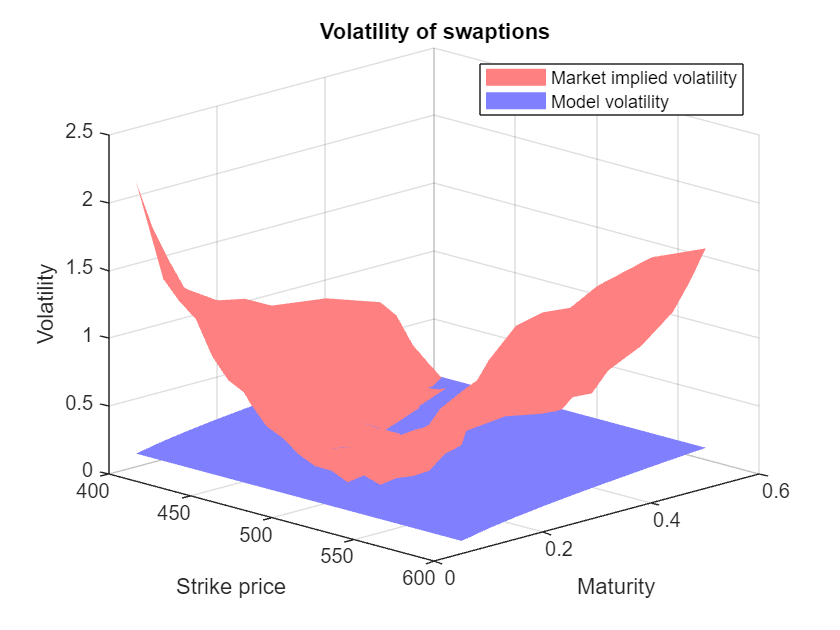

% volatilities
figure; hold on; grid on
surf(K, T, volatilities, 'FaceColor', [1 0.5 0.5], 'EdgeColor', 'none'); % in red
surf(K, T, model_volatilities_const, 'FaceColor', [0.5 0.5 1], 'EdgeColor', 'none'); % in blue

legend('Market implied volatility', 'Model volatility')
xlabel('Strike price'); ylabel('Maturity'); zlabel('Volatility');
title('Volatility of swaptions');
view(45,20);

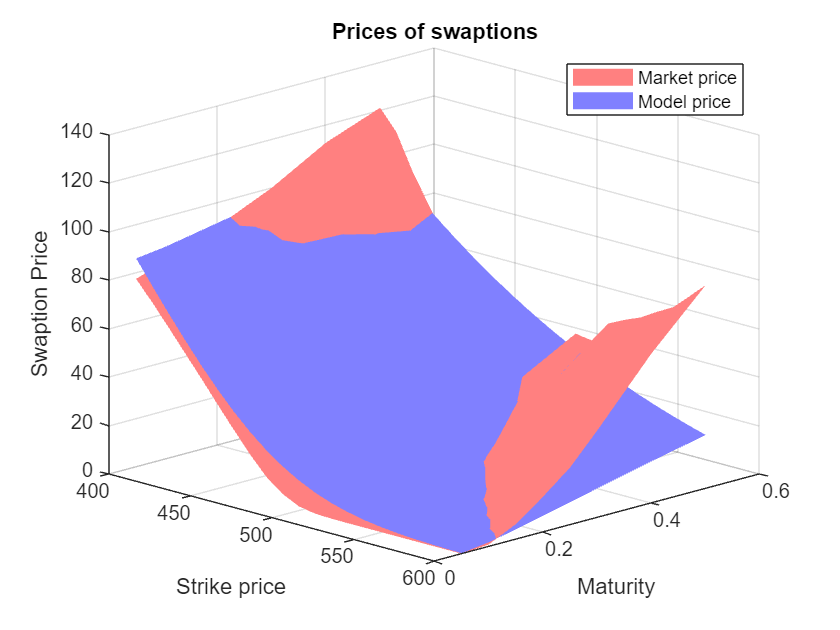


% second subplot: plot the prices
figure; hold on; grid on
surf(K, T, market_prices, 'FaceColor', [1 0.5 0.5], 'EdgeColor', 'none'); % in red
surf(K, T, model_prices_const, 'FaceColor', [0.5 0.5 1], 'EdgeColor', 'none'); % in blue

legend('Market price', 'Model price');
xlabel('Strike price'); ylabel('Maturity'); zlabel('Swaption Price')
title('Prices of swaptions');
view(45,20)

## Point IV: Calibration with time-dependent volatility

% Use the MSE as error function
func = @(x) MSE(market_prices, singleTimeDependentVolatilitySwaption(x(1:end-1), x(end), F0, K, T, DF));

% lower bounds (variances must be stricly positive, alpha must be stricly positive)
lb = zeros(length(T)+1, 1);

% initial guess, length(T)+1 random numbers between 0 and 1
x0 = max_volatility * rand(length(T)+1, 1);

% use fmincon to minimize the error function
[x_singletime, fval_singletime] = fmincon(func, x0, [], [], [], [], lb)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_singletime =     0.0009
    0.0027
    0.0054
    0.0099
    0.0126
    0.0153
    0.0400
    0.0458
    0.0717


fval_singletime = 131.9361

## Compute the model prices and volatilities

% compute the model prices
[model_prices_singletime, model_volatilities_singletime] = singleTimeDependentVolatilitySwaption( ...
    x_singletime(1:end-1), x_singletime(end), F0, K, T, DF);

% print the results
x_singletime(end)

ans = 0.0717

fval_singletime

fval_singletime = 131.9361

% recompute sigma hat
sigma_hat_singletime = sqrt( cumsum(x_singletime(1:end-1)) + x_singletime(end)^2 * T );
table(T, x_singletime(1:end-1), x_singletime(end)^2 * (T - [0; T(1:end-1)]), sigma_hat_singletime, ...
    'VariableNames', {'Tenor', 'Integral increase (Time dependent)', 'Integral increase (Constant)', 'Sigma hat'})

ans = 8×4 table
    Tenor    Integral increase (Time dependent)    Integral increase (Constant)    Sigma hat
    _____    __________________________________    ____________________________    _________

    0.05                 0.00092506                         0.00025682             0.034378 
     0.1                   0.002684                         0.00025682             0.064208 
    0.15                  0.0053568                         0.00025682             0.098673 
     0.2                  0.0099042                         0.00025682              0.14106 
    0.25                     0.0126                         0.00025682              0.18098 
     0.3                   0.015264                         0.00025682              0.21972 
     0.4                   0.039971                         0.00051364              0.29793 
     0.5  

## Plot the calibration

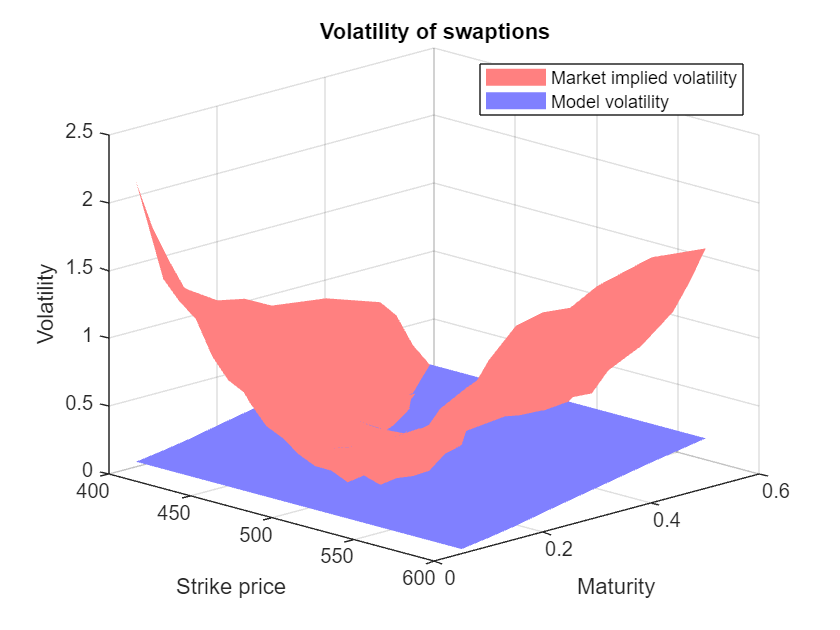

% volatilities
figure; hold on; grid on
surf(K, T, volatilities, 'FaceColor', [1 0.5 0.5], 'EdgeColor', 'none');
surf(K, T, model_volatilities_singletime, 'FaceColor', [0.5 0.5 1], 'EdgeColor', 'none');

legend('Market implied volatility', 'Model volatility')
xlabel('Strike price'); ylabel('Maturity'); zlabel('Volatility');
title('Volatility of swaptions');
view(45,20);

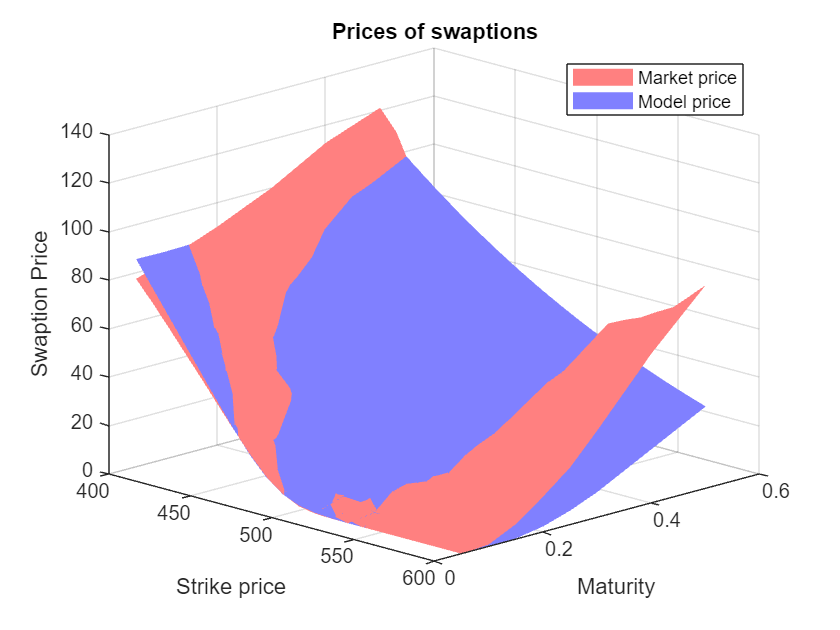


% prices
figure; hold on; grid on
surf(K, T, market_prices, 'FaceColor', [1 0.5 0.5], 'EdgeColor', 'none');
surf(K, T, model_prices_singletime, 'FaceColor', [0.5 0.5 1], 'EdgeColor', 'none');

legend('Market price', 'Model price');
xlabel('Strike price'); ylabel('Maturity'); zlabel('Swaption Price')
title('Prices of swaptions');
view(45,20);

## Point V: Calibration with two time-dependent volatilities

% Use the MSE as error function
func = @(x) MSE(market_prices, timeDependentVolatilitySwaption(x(:,1), x(:,2), F0, K, T, DF));

% lower bounds (variances must be stricly positive, alpha must be stricly positive)
lb = zeros(length(T), 2);

% initial guess, three random numbers between 0 and 1
x0 = max_volatility * rand(length(T), 2);

% use fmincon to minimize the error function
[x_time, fval_time] = fmincon(func, x0, [], [], [], [], lb)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_time =     0.0006    0.0006
    0.0015    0.0015
    0.0028    0.0028
    0.0051    0.0051
    0.0064    0.0064
    0.0078    0.0078
    0.0202    0.0202
    0.0231    0.0231


fval_time = 131.9361

## Store the results of the calibration

% compute the model prices
[model_prices_time, model_volatilities_time] = timeDependentVolatilitySwaption(...
    x_time(:,1), x_time(:,2), F0, K, T, DF);

% print the results
fval_time

fval_time = 131.9361

sigma_hat_time = sqrt( cumsum(x_time(:,1)) + cumsum(x_time(:,2)) );
table(T, x_time(:,1), x_time(:,2), sigma_hat_time, ...
    'VariableNames', {'Tenor', 'Integral increase (Sigma_1)', 'Integral increase (Sigma_2)', 'Sigma hat'})

ans = 8×4 table
    Tenor    Integral increase (Sigma_1)    Integral increase (Sigma_2)    Sigma hat
    _____    ___________________________    ___________________________    _________

    0.05             0.00059095                     0.00059095             0.034379 
     0.1              0.0014704                      0.0014704             0.064208 
    0.15              0.0028068                      0.0028068             0.098673 
     0.2              0.0050804                      0.0050806              0.14106 
    0.25              0.0064285                      0.0064284              0.18098 
     0.3                0.00776                      0.0077613              0.21972 
     0.4               0.020242                       0.020243              0.29793 
     0.5               0.023135                       0.023136              0.3674

## Plot the calibration

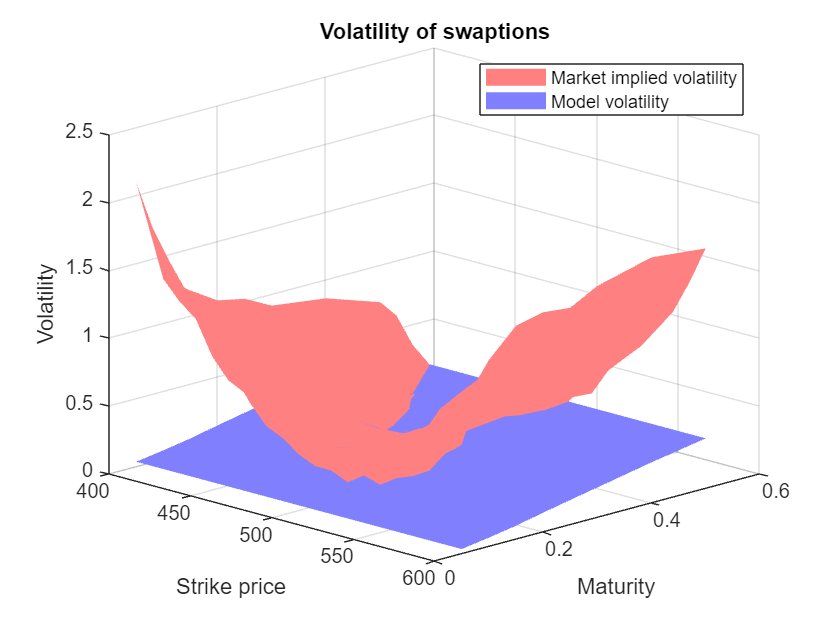

% sigma hats
figure; hold on; grid on
surf(K, T, volatilities, 'FaceColor', [1 0.5 0.5], 'EdgeColor', 'none');
surf(K, T, model_volatilities_time, 'FaceColor', [0.5 0.5 1], 'EdgeColor', 'none');

legend('Market implied volatility', 'Model volatility')
xlabel('Strike price'); ylabel('Maturity'); zlabel('Volatility');
title('Volatility of swaptions');
view(45,20);

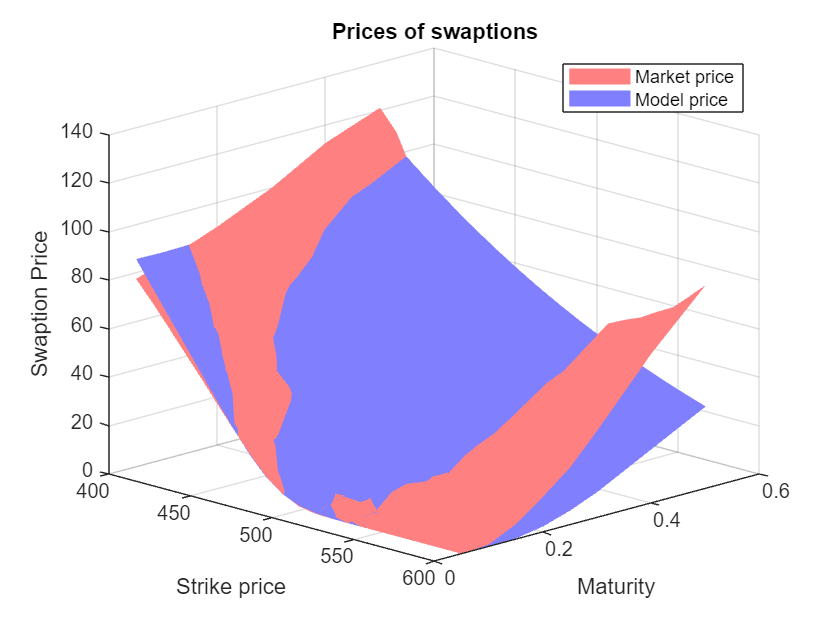


% prices
figure; hold on; grid on
surf(K, T, market_prices, 'FaceColor', [1 0.5 0.5], 'EdgeColor', 'none');
surf(K, T, model_prices_time, 'FaceColor', [0.5 0.5 1], 'EdgeColor', 'none');

legend('Market price', 'Model price');
xlabel('Strike price'); ylabel('Maturity'); zlabel('Swaption Price')
title('Prices of swaptions');
view(45,20);

## Point VI: Calibration with deterministic volatilities

% Use the MSE as error function
func = @(x) MSE(market_prices, deterministicVolatilitySwaption( ...
    x(1), x(2), x(3), T1, T2, F0, K, T, DF));

% lower bounds (variances must be stricly positive, alpha must be stricly positive)
lb = zeros(3, 1);

% initial guess, sigmas are betweeen 0 and max_volatility, alphas are between 1 and 2
x0 = [max_volatility * rand(1,1), rand(1,1)+1, max_volatility*rand(1,1)];

% use fmincon to minimize the error function
[x_det, fval_det] = fmincon(func, x0, [], [], [], [], lb)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x_det =     0.3741    2.5681    0.0001


fval_det = 135.6734

## Store the results of the calibration

% compute the model prices
[model_prices_det, model_volatilities_det] = deterministicVolatilitySwaption( ...
    x_det(1), x_det(2), x_det(3), T1, T2, F0, K, T, DF);

% print the results
x_det

x_det =     0.3741    2.5681    0.0001


fval_det

fval_det = 135.6734

## Plot the calibration

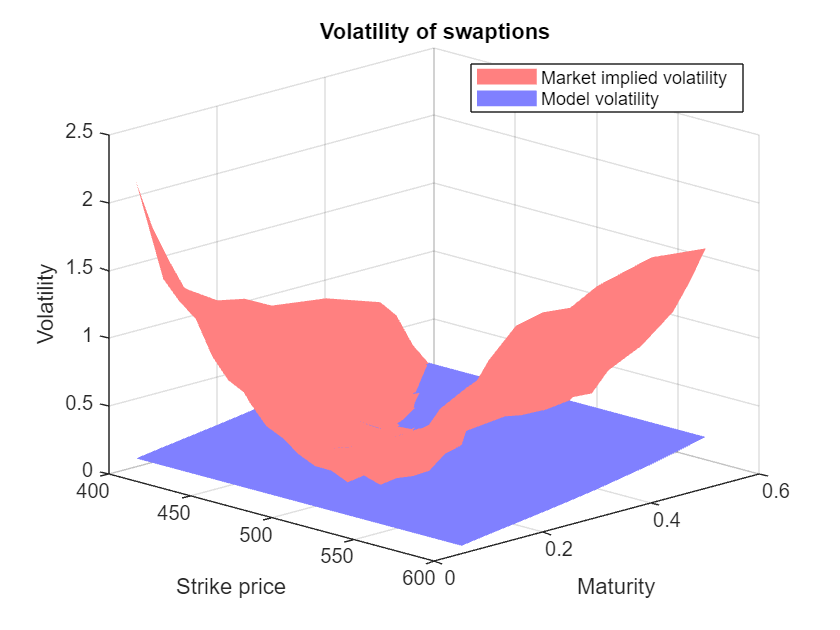

figure; hold on; grid on
surf(K, T, volatilities, 'FaceColor', [1 0.5 0.5], 'EdgeColor', 'none');
surf(K, T, model_volatilities_det, 'FaceColor', [0.5 0.5 1], 'EdgeColor', 'none');

legend('Market implied volatility', 'Model volatility')
xlabel('Strike price'); ylabel('Maturity'); zlabel('Volatility');
title('Volatility of swaptions');
view(45,20);

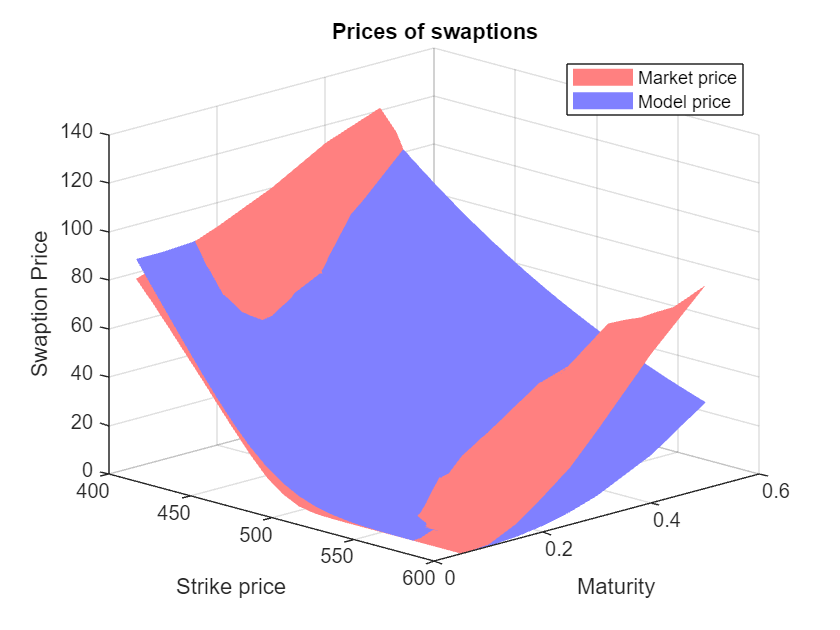

% prices
figure; hold on; grid on
surf(K, T, market_prices, 'FaceColor', [1 0.5 0.5], 'EdgeColor', 'none');
surf(K, T, model_prices_det, 'FaceColor', [0.5 0.5 1], 'EdgeColor', 'none');

legend('Market price', 'Model price');
xlabel('Strike price'); ylabel('Maturity'); zlabel('Swaption Price')
title('Prices of swaptions');
view(45,20);

## Point VII: setup

K_barrier = 500; % strike price
L = 450; % barrier level
T_barrier = 0.5; % maturity

## Point VII, a: pricing a down-and-in call option, using the constant volatility model

% integral is (sigma_1^2 + sigma_2^2) * (T_n - T_{n-1})
sigma_int_inc = (x_const(1)^2 + x_const(2)^2) * (T - [0; T(1:end-1)]);

Sim_const = MC_simulation(sigma_int_inc, F0, T);

% find which rows have gone below the barrier
below_barrier = any(Sim_const < L, 2);

C_DI_const_MC = max(Sim_const(:,end) - K_barrier, 0) .* below_barrier;
C_DI_const_MC = mean(C_DI_const_MC) * DF(end);

## Point VII, b: pricing a down-and-in call option, using the single time-dependent volatility model

sigma_int_inc = x_singletime(1:end-1) + x_singletime(end)^2 * (T - [0; T(1:end-1)]);

Sim_singletime = MC_simulation(sigma_int_inc, F0, T);

% find which rows have gone below the barrier
below_barrier = any(Sim_const < L, 2);

C_DI_singletime_MC = max(Sim_singletime(:,end) - K_barrier, 0) .* below_barrier;
C_DI_singletime_MC = mean(C_DI_singletime_MC) * DF(end);

## Point VII, c: pricing a down-and-in call option, using the time-dependent volatility model

sigma_int_inc = x_time(:,1) + x_time(:,2);

Sim_time = MC_simulation(sigma_int_inc, F0, T);

% find which rows have gone below the barrier
below_barrier = any(Sim_const < L, 2);

C_DI_time_MC = max(Sim_time(:,end) - K_barrier, 0) .* below_barrier;
C_DI_time_MC = mean(C_DI_time_MC) * DF(end);

## Print the results

table(C_DI_const_MC, C_DI_singletime_MC, C_DI_time_MC, ...
    'VariableNames', {'Constant volatility', 'Single time-dependent volatility', 'Time-dependent volatility'}, ...
    'RowNames', {'Down-and-in call option price'})

ans = 1×3 table
                                     Constant volatility    Single time-dependent volatility    Time-dependent volatility
                                     ___________________    ________________________________    _________________________

    Down-and-in call option price          11.979                        44.716                          43.507          
